%Cruise system model 

m = 1000;
b= 50;

s= tf('s');
P_cruise = 1/(m*s+b);
t_cruise = 0:0.1:30;
r_cruise = 10;

t_system = t_cruise;
P_system = P_cruise;
r_system = r_cruise;



%P control
%Transient error
Kp = 1000;
C  = Kp;
sys_cl = feedback(C*P_system,1);
figure(1);
step(r_system*sys_cl,t_system);
ylabel('Amplitude');
title('Response to aStep Reference with Different Values of K_p')

%type 0 시스템이므로 steday-state error 0으로 줄일 수 없음


%step disturbance 

Kp = 1000;
C  = Kp;
dist_cl = feedback(P_system,C);
figure(2);
step(dist_cl,t_system);
ylabel('Position,\theta(radians)');
title('Response to a Step Disturbance with Different Values of K_p')

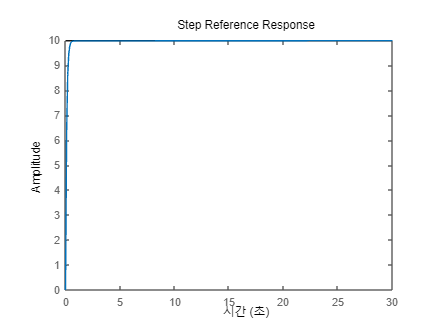

%PI control

Kp = 1000;
Ki = 150;
C = Kp+Ki/s;
sys_cl = feedback(C*P_system,1);
figure(3)
step(r_system*sys_cl,t_system);
ylabel('Amplitude')
title('Step Reference Response');

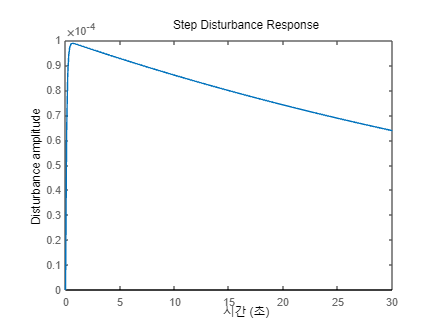

figure(4);
dist_cl=feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude')
title('Step Disturbance Response')

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.2221
    TransientTime: 0.4085
     SettlingTime: 0.4085
      SettlingMin: 0.9013
      SettlingMax: 0.9966
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9966
         PeakTime: 2.7948


%type 1로 steady-state error 0으로 수렴

% PID control

Kp = 1000;
Ki = 150;
Kd = 10;
C = Kp+Ki/s+Kd*s;
sys_cl = feedback(C*P_system,1);
figure(5)
step(r_system*sys_cl,t_system);
ylabel('Amplitude')
title('Step Reference Response');
figure(6);
dist_cl=feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude')
title('Step Disturbance Response')

%Cruise 는 1차 시스템이므로 PID제어는 큰 효율이 없음
stepinfo(sys_cl)

% Motor system (position control) - 3차 시스템(모터위치제어)

J= 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
L = 2.75E-6;
R = 4;
s=tf('s');
t_motor = 0:0.001:0.3;
r_motor = 1; %radian
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

t_system = t_motor;
P_system = P_motor;
r_system = r_motor;

%P control

Kp = 30;
C  = Kp;
sys_cl = feedback(C*P_system,1);
figure(1);
step(r_system*sys_cl,t_system);
ylabel('Amplitude');
title('Response to aStep Reference with Different Values of K_p')
%step disturbance 

Kp = 30;
C  = Kp;
dist_cl = feedback(P_system,C);
figure(2);
step(dist_cl,t_system);
ylabel('Position,\theta(radians)');
title('Response to a Step Disturbance with Different Values of K_p')

%PI control

Kp = 30;
Ki = 1000;
C = Kp+Ki/s;
sys_cl = feedback(C*P_system,1);
figure(3)
step(r_system*sys_cl,t_system);
ylabel('Amplitude')
title('Step Reference Response');
figure(4);
dist_cl=feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude')
title('Step Disturbance Response')

% PID control

Kp = 30;
Ki = 1000;
Kd = 0.25;
C = Kp+Ki/s+Kd*s;
sys_cl = feedback(C*P_system,1);
figure(5)
step(r_system*sys_cl,t_system);
ylabel('Amplitude')
title('Step Reference Response');
figure(6);
dist_cl=feedback(P_system,C);
step(dist_cl,t_system);
ylabel('Disturbance amplitude')
title('Step Disturbance Response')

stepinfo(sys_cl)

%PID Tuner
pidTuner(P_system,'pid')